syms mu_core I n l z r theta_1 theta_2 % Electromagnet parameters
syms m % Magnet parameters

assume([mu_0 mu_core I n l z r p l_mag theta_1 theta_2], 'real')
assumeAlso([z r], 'positive')

struct_params = struct();

% Linearization points
struct_params.z_bar = 0.04;
struct_params.I_bar = 0.02;

% Radius of the electromagnet coil
% - Units: m
struct_params.r = 0.01;

% Length of the electromagnet coil
% - Units: m
struct_params.l = 0.02; % Length of inductor (m)

% Lumped scaling constant: A m^3
% - winding_count*mu_core
% - Units: kg m^3 / s^2 A = N m^2 / A
struct_params.k = 6.3e-3*1e4;

% Magnitude of the magnetic dipole moment of the permanent magnet
% - Units: amp-meters^2
struct_params.m = 0.03*48;

% Resistance of the coil
% - Units: Ohms
struct_params.R = 2.41;
struct_params.M = 0.05; % Mass of permanent magnet

% Magnetic field of the solenoid
B_em = (mu_core/2)*I*(n/l) * int(r^2/((r^2+z^2)^1.5), z, z, z+l)

$$B\_em = -\frac{\text{I}\,\mu_{\mathrm{core}}\,n\,\left(\frac{z}{\sqrt{r^{2}+z^{2}}}-\frac{l+z}{\sqrt{{\left(l+z\right)}^{2}+r^{2}}}\right)}{2\,l}$$

Here we can lump $\mu_{core} \cdot n$ into a single paramter $K$ for parametrizing the electromagnet's field strength.

syms k
assume(K, 'real')
B_em = subs(B_em, mu_core * n, k)

$$B\_em = -\frac{\text{I}\,k\,\left(\frac{z}{\sqrt{r^{2}+z^{2}}}-\frac{l+z}{\sqrt{{\left(l+z\right)}^{2}+r^{2}}}\right)}{2\,l}$$

#### Calculate force:

Using $F = \nabla(\vec m \cdot \vec B)$, but with $\vec m = p\cdot l_{mag} \hat{k}$ where $p$ is the pole strength of the magnet and $l \hat{k}$ is the vector pointing from south to north pole of the magnet

force = m*simplify(diff(B_em, z))

$$force = \frac{\text{I}\,k\,m\,\left(\frac{1}{\sqrt{{\left(l+z\right)}^{2}+r^{2}}}-\frac{1}{\sqrt{r^{2}+z^{2}}}+\frac{z^{2}}{{\left(r^{2}+z^{2}\right)}^{3/2}}-\frac{\left(2\,l+2\,z\right)\,\left(l+z\right)}{2\,{\left({\left(l+z\right)}^{2}+r^{2}\right)}^{3/2}}\right)}{2\,l}$$

#### Linerization:

Equation of motion: $mg + F_{mag}(i, z) = m \ddot z$ where current $i = i(t)$ and position $z = z(t)$are both time-varying signals.

Linearize:


$$m\ddot z = mg + F'_{mag}(\bar i, \bar z) + F_{mag_z}(\bar i, \bar z)(z - \bar z) +  F_{mag_i}(\bar i, \bar z)(i - \bar i)$$


The taylor series expansion simplifies out to a linear combination of $z$, $i$, and a constant term:


$$m\ddot z = mg + Az + Bi + C$$


syms I_bar z_bar % Linearization point
assume([I_bar z_bar], 'real')

% Multivariable taylor series:
% linearize f(x, y) about a,b = f(a, b) + f_x(a, b)(x-a) + f_y(a, b)(y-b)
f_eval = @(sym_exp) (subs(sym_exp, [I, z], [I_bar, z_bar]));
lin_force = f_eval(force) + f_eval(diff(force, z))*(z-z_bar) + f_eval(diff(force, I))*(I-I_bar);
lin_force = simplify(lin_force);

% Display linearized force equation
lin_force

$$lin\_force = \begin{array}{l} \frac{k\,m\,r^{2}\,\left(\text{I}\,l^{2}\,\sigma_{1}-\text{I}\,{\bar{z}}^{2}\,\sigma_{2}-3\,\bar{I}\,{\bar{z}}^{2}\,\sigma_{2}-\text{I}\,r^{2}\,\sigma_{2}+\text{I}\,r^{2}\,\sigma_{1}+\text{I}\,{\bar{z}}^{2}\,\sigma_{1}+3\,\bar{I}\,{\bar{z}}^{2}\,\sigma_{1}-3\,\bar{I}\,z\,\bar{z}\,\sigma_{1}+3\,\bar{I}\,z\,\bar{z}\,\sigma_{2}-3\,\bar{I}\,l\,z\,\sigma_{1}+2\,\text{I}\,l\,\bar{z}\,\sigma_{1}+3\,\bar{I}\,l\,\bar{z}\,\sigma_{1}\right)}{2\,l\,\sigma_{1}\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(r^{2}+{\bar{z}}^{2}\right)}^{5/2}\\ \sigma_{2}={\left({\left(l+\bar{z}\right)}^{2}+r^{2}\right)}^{5/2} \end{array}$$

% Extract the coefficients for each variable
[cfs, correspondences] = coeffs(lin_force, [z, I]);
cfs

$$cfs = \begin{array}{l} \left(\begin{array}{ccc} -\frac{k\,m\,r^{2}\,\left(3\,\bar{I}\,l\,\sigma_{1}-3\,\bar{I}\,\bar{z}\,\sigma_{2}+3\,\bar{I}\,\bar{z}\,\sigma_{1}\right)}{2\,l\,\sigma_{1}\,\sigma_{2}} & \frac{k\,m\,r^{2}\,\left(l^{2}\,\sigma_{1}-{\bar{z}}^{2}\,\sigma_{2}-r^{2}\,\sigma_{2}+r^{2}\,\sigma_{1}+{\bar{z}}^{2}\,\sigma_{1}+2\,l\,\bar{z}\,\sigma_{1}\right)}{2\,l\,\sigma_{1}\,\sigma_{2}} & \frac{k\,m\,r^{2}\,\left(3\,\bar{I}\,{\bar{z}}^{2}\,\sigma_{1}-3\,\bar{I}\,{\bar{z}}^{2}\,\sigma_{2}+3\,\bar{I}\,l\,\bar{z}\,\sigma_{1}\right)}{2\,l\,\sigma_{1}\,\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(r^{2}+{\bar{z}}^{2}\right)}^{5/2}\\ \sigma_{2}={\left({\left(l+\bar{z}\right)}^{2}+r^{2}\right)}^{5/2} \end{array}$$

These coefficients each correspond to the following parameters

correspondences

$$correspondences = \left(\begin{array}{ccc} z & \text{I} & 1 \end{array}\right)$$

The $1$ indicates a constant term. These are our $A, B,$ and $C$.

We now have our magnetic input force as a linear combination of inputs ($i$) and outputs($z$)

### Transfer function

With this linear combination, we can now calculate the laplace transform:


$$ms^2z = Az + BI + \frac{1}{s}(C + mg)$$


For modelling the circuit, we will ignore the inductance of the electromagnet and instead model it as a resistor. This is because, as we can see from typical

Using impedance for an resistor circuit, $V = IR$. We can now substitute $I = \frac{V}{R}$ into the previous equation:


$$ms^2z = Az + B\frac{V}{R} + \frac{1}{s}(C+mg)$$


Now our job is to solve for a transfer function with disturbances.

syms s m g R L V A B C
assume([m g R L V A B C], "real")
assumeAlso([g, R, L], "positive")
tf_miso = m*s^2*z == A*z + B*(V/R) + (C + m*g)/s;
tf_miso = isolate(tf_miso, z)

$$tf\_miso = z=-\frac{\frac{C+g\,m}{s}+\frac{B\,V}{R}}{A-m\,s^{2}}$$

cfs_tf = coeffs(rhs(tf_miso), V)

$$cfs\_tf = \left(\begin{array}{cc} -\frac{C+g\,m}{s\,\left(A-m\,s^{2}\right)} & -\frac{B}{R\,\left(A-m\,s^{2}\right)} \end{array}\right)$$

% First coeff is for constants, second is for V
tf_gravity = z == cfs_tf(1)

$$tf\_gravity = z=-\frac{C+g\,m}{s\,\left(A-m\,s^{2}\right)}$$

tf_controlled = z == cfs_tf(2)

$$tf\_controlled = z=-\frac{B}{R\,\left(A-m\,s^{2}\right)}$$

#### Substitute in parameters:

B_particular = subs(B_em, struct_params);
force_particular = subs(force, struct_params);
lin_force_particular = subs(lin_force, struct_params);
coeffs_particular = eval(subs(cfs, struct_params));

f_B = matlabFunction(B_particular);
f_force = matlabFunction(force_particular);
f_lin_force_particular = matlabFunction(lin_force_particular);

### Construct transfer function

val_A = coeffs_particular(1);
val_B = coeffs_particular(2);
val_C = coeffs_particular(3);

tf_obj_gravity = tf(-1*(coeffs_particular(3)+9.8*struct_params.M), [-struct_params.M, 0, coeffs_particular(1), 0])

tf_obj_gravity =
 
        -143
  -----------------
  0.05 s^3 - 3588 s
 
Continuous-time transfer function.



tf_obj_controlled = tf(val_B, struct_params.R*[-struct_params.m, 0, val_A])

tf_obj_controlled =
 
       2228
  ---------------
  3.47 s^2 - 8646
 
Continuous-time transfer function.



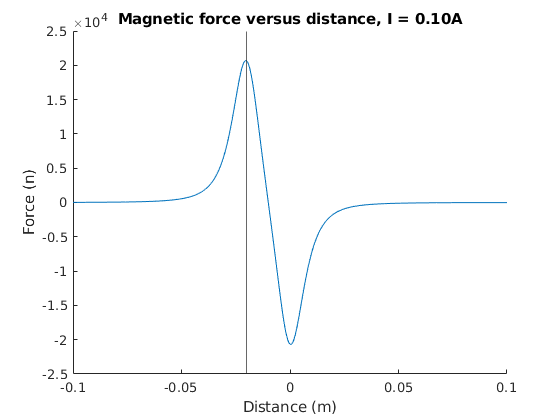

% Constant current, varying position:
I_val = 0.1; % amps
z_val = linspace(-0.1, 0.1, 1000); % meters
v_force = f_force(I_val, z_val);

figure()
hold on

plot(z_val, v_force);
xline(-struct_params.l);

title(sprintf("Magnetic force versus distance, I = %.2fA", I_val))
xlabel("Distance (m)")
ylabel("Force (n)")

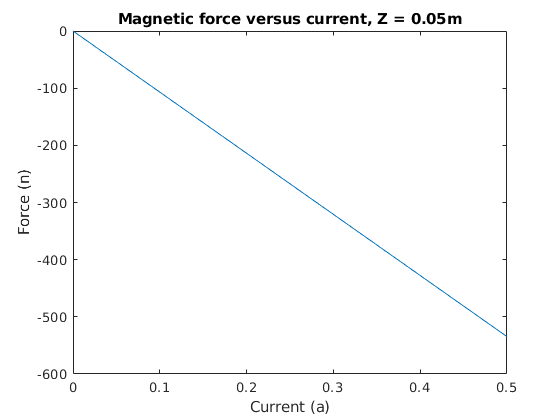

z_val = 0.05; % meters
I_val = linspace(0, 0.5, 1000); % amps
v_force = f_force(I_val, z_val);

figure()
plot(I_val, v_force)
title(sprintf("Magnetic force versus current, Z = %.2fm", z_val))
xlabel("Current (a)")
ylabel("Force (n)")